% 回归分析预测工业增加值变化规律
clear all; clc;
% 读取数据
file = '月度数据.xls';
[NUM,~,~]=xlsread(file);

% 缺失值填补，采用线性插补法
d2 = fillmissing(NUM,'linear');

% 数据变换
d3 = d2;
d3(:,end-2:end-1) = []; %删除第二产业增加值和利润
% 人均可支配收入前的空缺行删除，只保留2013-09之后的
index = find(d3(:,11) == 13556.5);
d3(1:index-1,:) = [];
%d3_stan = stan(d3);  %标准化后的数据，min-max标准化

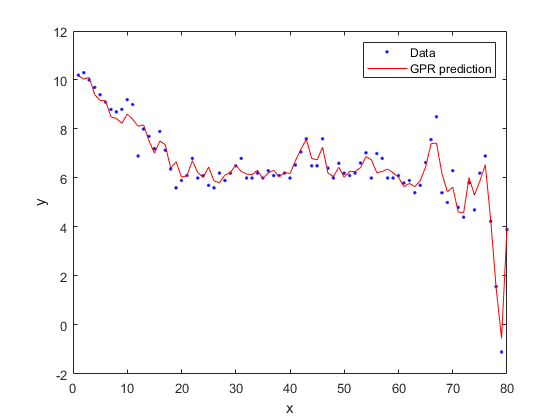

% 模型训练
rng(0,'twister');
%高斯过程回归
[GPR, GPR_RMSE] = GPR_SQ(d3); 
GPRmodel = GPR.RegressionGP;
x = 1:length(d3);
y = d3(:,end); %目标变量
ypre = resubPredict(GPRmodel); %目标变量的预测值
plot(x,y,'b.',x,ypre,'r');
xlabel('x');
ylabel('y');
legend('Data','GPR prediction');
hold off;

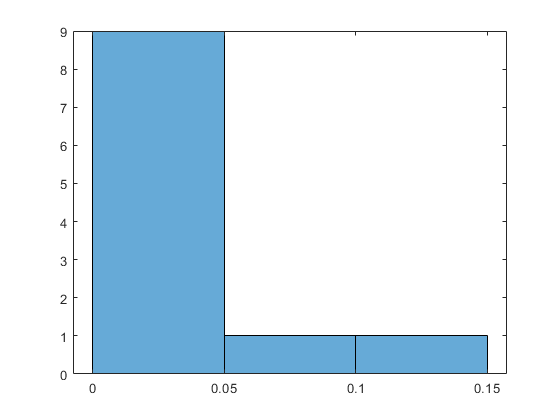

% 决策树
[Dtree, Dtree_RMSE] = DecisionTree(d3);
Dtreemodel = Dtree.RegressionTree;
imp = predictorImportance(Dtreemodel);
histogram(imp);

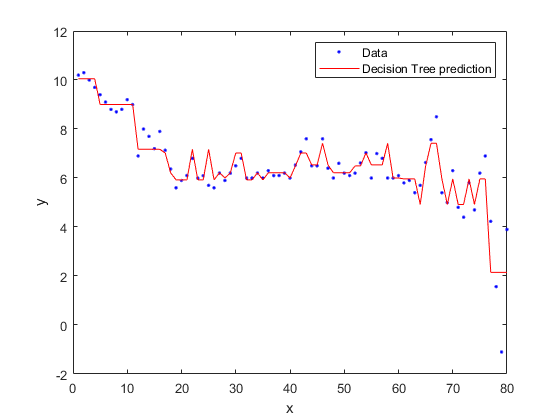

ypre2 = resubPredict(Dtreemodel);
plot(x,y,'b.',x,ypre2,'r');
xlabel('x');
ylabel('y');
legend('Data','Decision Tree prediction');
hold off;

% 线性回归
[LR, linearRMSE] =  LinearRegression(d3);
LRmodel = Dtree.RegressionTree;
imp2 = predictorImportance(LRmodel);
histogram(imp2);

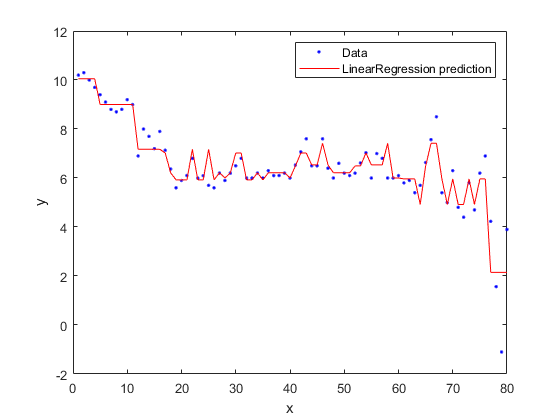

ypre3 = resubPredict(LRmodel);
plot(x,y,'b.',x,ypre3,'r');
xlabel('x');
ylabel('y');
legend('Data','LinearRegression prediction');
hold off;

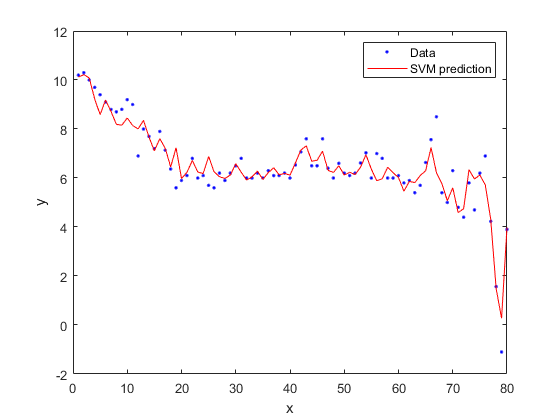

% 支持向量机
[SVMm, SVM_RMSE] =  SVM(d3);
SVMmodel = SVMm.RegressionSVM;
ypre4 = resubPredict(SVMmodel);
plot(x,y,'b.',x,ypre4,'r');
xlabel('x');
ylabel('y');
legend('Data','SVM prediction');
hold off;

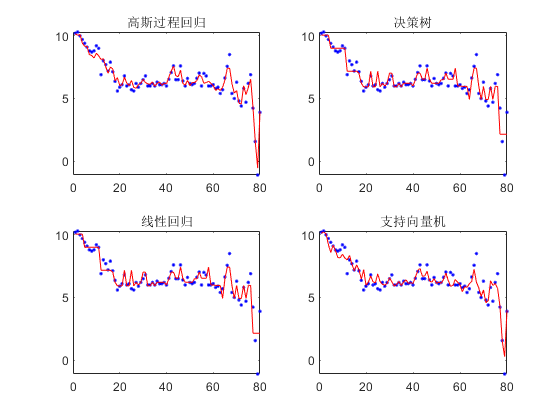

% 模型评估
subplot(2,2,1)
plot(x,y,'b.',x,ypre,'r');
title('高斯过程回归');

subplot(2,2,2)
plot(x,y,'b.',x,ypre2,'r');
title('决策树');

subplot(2,2,3)
plot(x,y,'b.',x,ypre3,'r');
title('线性回归');

subplot(2,2,4)
plot(x,y,'b.',x,ypre4,'r');
title('支持向量机');
hold off

% 预测接下来6个月的自变量数据
% 用前6个月数据的均值作为下一个月的预测值
[m,n] = size(d3);
Nan = nan(1,n);
d4 = [d3;Nan;Nan;Nan;Nan;Nan;Nan;Nan;Nan;Nan];
for i = 1:9
    d4 = fillmissing(d4,'movmean',12);
end

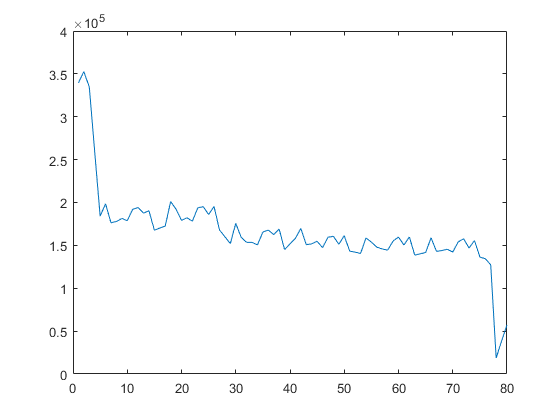

% 客运量单独处理
%2月份之后month个月内客运量恢复到疫情前（即2月份前）半年平均水平
% month包括2到4月份3个月的数据，也就是说只需要预测month-3个月的数据即可
month = 8; 
keyun = d3(:,end-2);
plot(x,keyun)

average_keyun = mean(keyun(end-9:end-3));
k3 = d4(end-8:end,10);
k3(month) = average_keyun; %此处有问题，应-3
k3(4:month-1) = nan;
k3 = fillmissing(k3,'linear');

% 出口交货值
output = d3(:,1);
out_ave = mean(output(end-9:end-3));
o3 = d4(end-8:end,1);
o3(month) = out_ave;
o3(4:month-1) = nan;
o3 = fillmissing(o3,'linear');

% 合并预测数据
d4_6 = d4(81:80+month-3,:);
d4_6(:,10) = k3(4:month);
d4_6(:,1) = o3(4:month);
d4_6(:,end) = [];
result_pre = predict(GPRmodel,d4_6)

result_pre =     2.8703
    2.8610
    3.0972
    3.7502
    5.1748


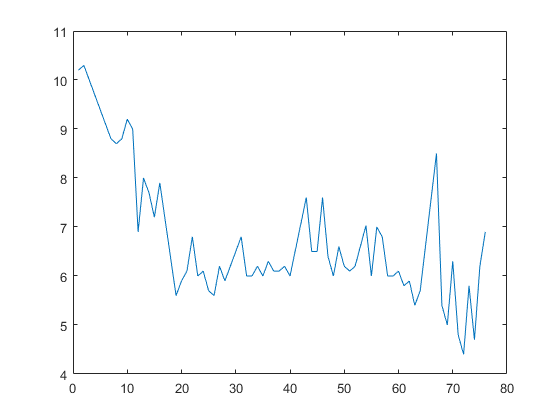

%% 不考虑疫情时的工业增长率
ratio = d3(1:end-4,end);
x1 = 1:length(ratio);
plot(x1,ratio)

d5 = [x1',ratio];
[R, validationRMSE3] = Ratio(d5);
Rmodel = R.RegressionGP;
xpre = 77:80+month-3;
xpre = xpre';
result_older = predict(Rmodel,xpre);
result_old = result_older(3:end)

result_old =     6.6373
    6.6694
    6.6999
    6.7290
    6.7566
    6.7828
    6.8078


## 损失估计

% 增长率损失，因为有滞后性，从3月份开始算起
result_pre = [d3(end-1:end,end);result_pre]

result_pre =    -1.1000
    3.9000
    2.8703
    2.8610
    3.0972
    3.7502
    5.1748


loss_ratio = result_old - result_pre %工业增加值增长率损失

loss_ratio =     7.7373
    2.7694
    3.8297
    3.8680
    3.6594
    3.0326
    1.6330



% 每个月的工业增加值_累计值
plusC = NUM(:,end-1);
plusC(1:8) = fillmissing(plusC(1:8),'linear');
for i = 1:9
    plusC(i*12-3:i*12+8) = fillmissing(plusC(i*12-3:i*12+8),'linear');
end

% 工业增加值损失等于去年同期的工业增加值_当期乘以增长率损失
plus = diff(plusC); %工业增加值_当期
loss_plus = plus(106:106+month-2).*loss_ratio

loss_plus = 	1.0e+05 *

    2.5099
    0.8984
    1.2423
    1.2547
    1.1928
    0.9885
    0.5323


loss_accu = sum(loss_plus);
fprintf('%i个月内完全恢复生产的工业增加值累计损失%.0f亿元\n',month,loss_accu)

8个月内完全恢复生产的工业增加值累计损失861890亿元


out = [result_old,result_pre,loss_ratio,loss_plus]

out = 	1.0e+05 *

    0.0001   -0.0000    0.0001    2.5099
    0.0001    0.0000    0.0000    0.8984
    0.0001    0.0000    0.0000    1.2423
    0.0001    0.0000    0.0000    1.2547
    0.0001    0.0000    0.0000    1.1928
    0.0001    0.0000    0.0000    0.9885
    0.0001    0.0001    0.0000    0.5323



loss_income = loss_plus/0.35;
loss_income_accu = sum(loss_income);
fprintf('%i个月内完全恢复生产的营业收入累计损失%.0f亿元\n',month,loss_income_accu)

8个月内完全恢复生产的营业收入累计损失2462544亿元


## 画图

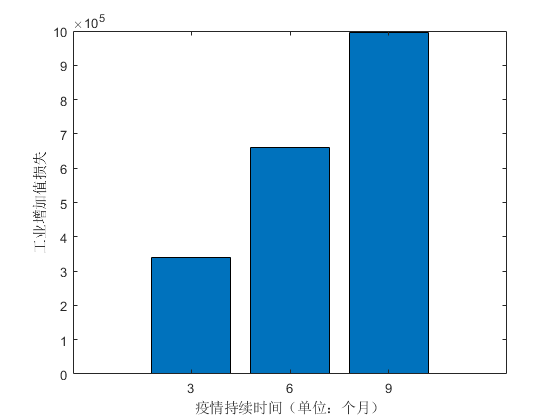

figure(2)
xx = 3:3:9;
yy(1) = 340822;
yy(2) = 659750;
yy(3) = 994842;
bar(xx,yy,'DisplayName','yy')
xlabel('疫情持续时间（单位：个月）')
ylabel('工业增加值损失')

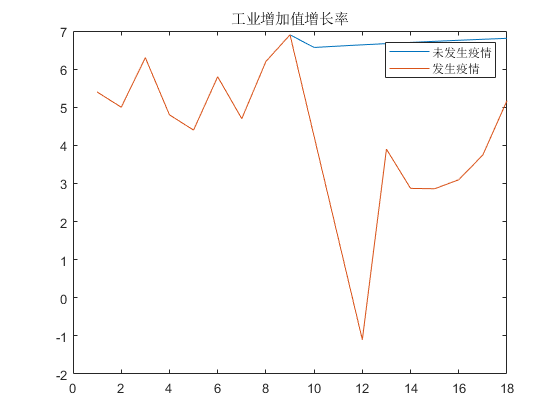


% 月份
aa = 1:12;
aa = [aa';aa'];
ab = ones(12,1)*2019;
ac = ones(12,1)*2020;
ab = [ab;ac];
aa = [ab,aa];
%x_axis(:,1) = datenum(aa(:,1:end));

% 增长率损失
figure(3)
r_old = [d3(end-12:end-4,end); result_older];
r_pre = [d3(end-12:end-2,end); result_pre];
xre = 1:length(r_pre);
plot(xre,r_old,xre,r_pre)
legend('未发生疫情','发生疫情')
title('工业增加值增长率')

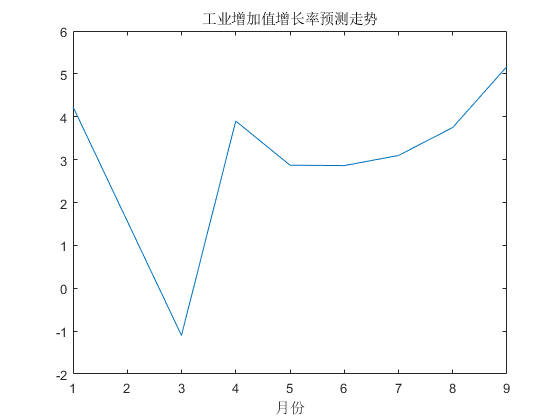

%xtickformat('M')

%增长率预测走势
figure(4)
ra = r_pre(end-8:end);
xra = 1:length(ra);
plot(xra,ra)
xlabel('月份')
title('工业增加值增长率预测走势')

%dateaxis('x',5)
%xtickformat('M')
